Breakaway connector pin position calculator

Takes in the radius of the connector and the pin locations, and returns the x,y coordinates of each pin.

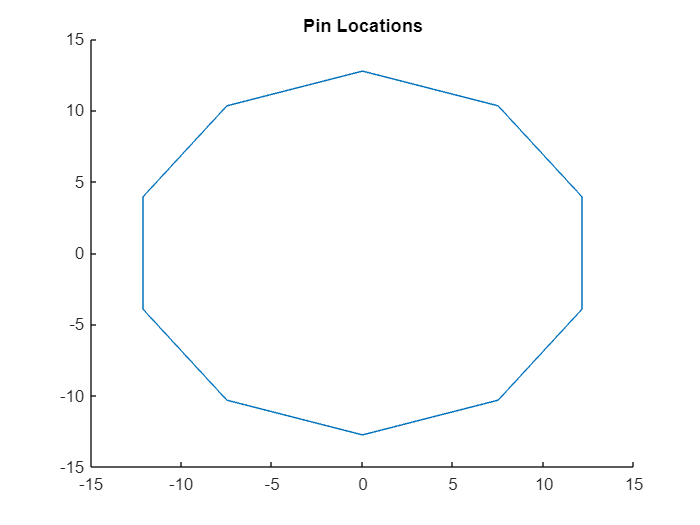

radius=12.75;%just an example
num_pins = 10;
theta=linspace(0,2*pi,num_pins+1);%you can increase this if this isn't enough yet
x=radius*cos(theta);
y=radius*sin(theta);
theta=90;
rot = [];
R = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];
for i = 1:size(x)
    rot = [rot R*[x;y]];
end
figure
hold on
plot(rot(1,:),rot(2,:))

title("Pin Locations")

disp('Coordinates:')

Coordinates:


disp(rot(:,1:10))

         0   -7.4943  -12.1260  -12.1260   -7.4943   -0.0000    7.4943   12.1260   12.1260    7.4943
   12.7500   10.3150    3.9400   -3.9400  -10.3150  -12.7500  -10.3150   -3.9400    3.9400   10.3150

